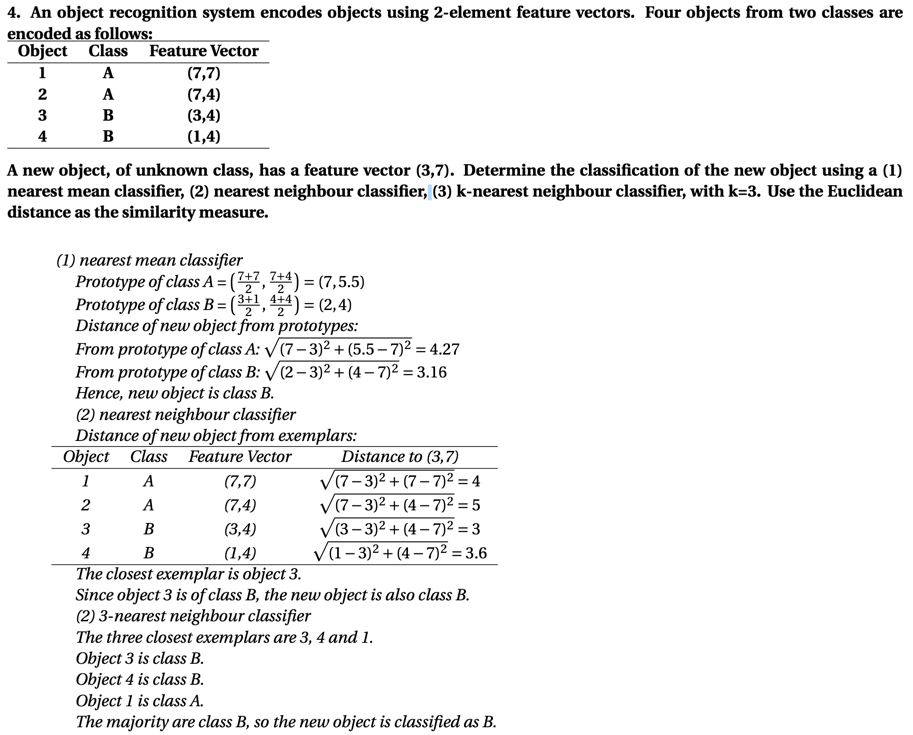

% (1) Nearest mean classifier
O1_A = [7 7];
O2_A = [7 4];
O3_B = [3 4];
O4_B = [1 4];
new_obj = [3 7];
prototype_A = (O1_A + O2_A) / 2;
prototype_B = (O3_B + O4_B) / 2;
% minimum
distance_from_A_to_new_obj = pdist2(prototype_A, new_obj, "euclidean")

distance_from_A_to_new_obj = 4.2720

distance_from_B_to_new_obj = pdist2(prototype_B, new_obj, "euclidean")

distance_from_B_to_new_obj = 3.1623


% (2) Nearest neighbour classifier
% Minimum
distance_from_O1_to_new_obj = pdist2(O1_A, new_obj, "euclidean")

distance_from_O1_to_new_obj = 4

distance_from_O2_to_new_obj = pdist2(O2_A, new_obj, "euclidean")

distance_from_O2_to_new_obj = 5

distance_from_O3_to_new_obj = pdist2(O3_B, new_obj, "euclidean")

distance_from_O3_to_new_obj = 3

distance_from_O4_to_new_obj = pdist2(O4_B, new_obj, "euclidean")

distance_from_O4_to_new_obj = 3.6056


% (3) 3-nearest neighbour classifier
% The three closest examplars are 3,4 and 1.
% Object 3 is class B.
% Object 4 is class B.
% Object 1 is class A.
% The majority are class B, so the new object is classified as B.

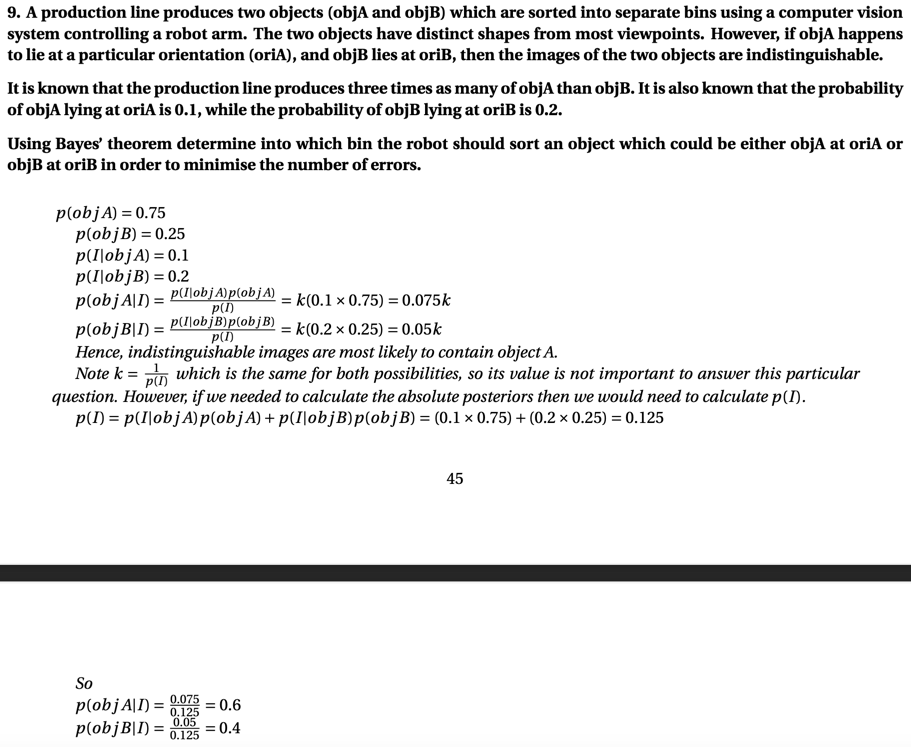

P_A = 0.75;
P_B = 0.25;
P_I_given_A = 0.1;
P_I_given_B = 0.2;
P_I = P_I_given_A * P_A + P_I_given_B * P_B;

P_I = 0.1250


P_A_given_I = P_I_given_A * P_A / P_I

P_A_given_I = 0.6000

P_B_given_I = P_I_given_B * P_B / P_I

P_B_given_I = 0.4000